### IDVGVB-0の分析

SiO2

vg0 = 0.580000
id0 = 0.286370
Vth = 0.247108


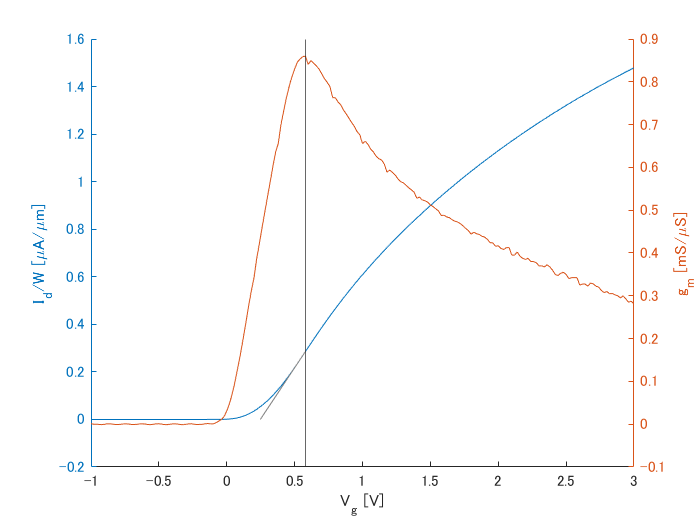

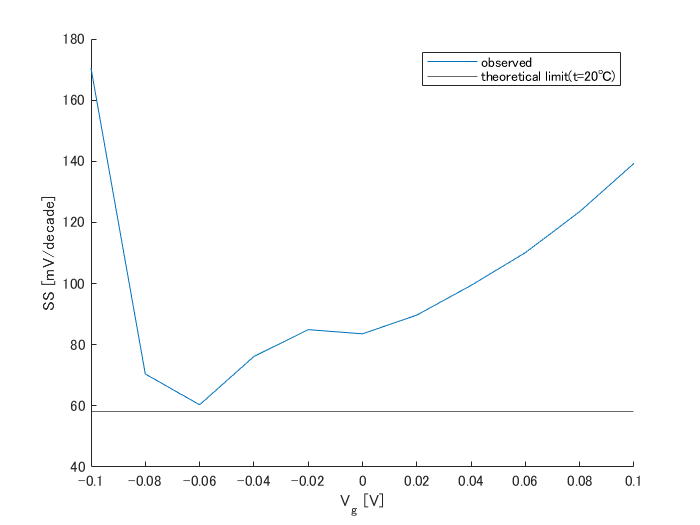

(Vg, SS) at SS's minimum: (-0.060000, 60.349776)


raw1 = readmatrix("IDVGVB-0.TXT");
dat1 = raw1(203:403, 2:3);
analyze(dat1, [-0.1, 0.1], "SiO2");

### IDVGHFO2の分析

raw2 = readmatrix("IDVGHFO2.TXT");

#### ヒステリシスがあることを確認

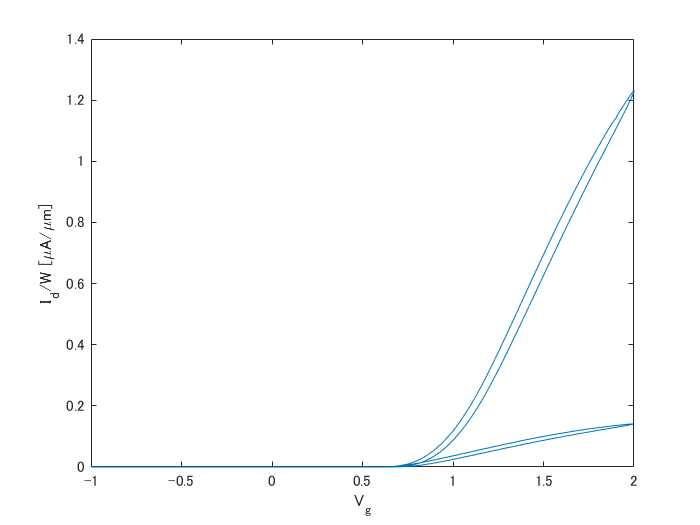

rawplot(raw2);

#### 「行き」(Vgが大きくなる部分)のみを見て、Vthを計算

vg0 = 1.120000
id0 = 0.052497
Vth = 0.729688


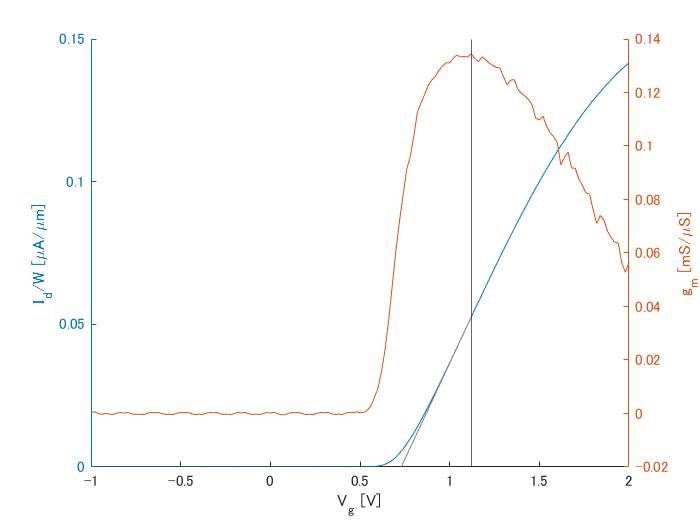

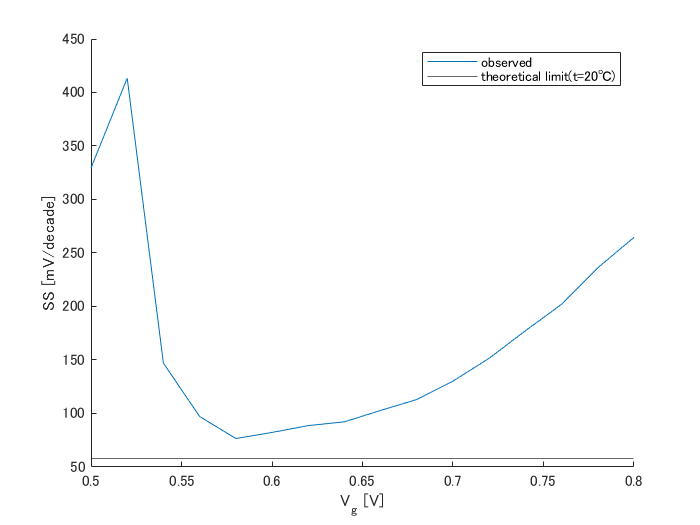

(Vg, SS) at SS's minimum: (0.580000, 76.617457)


dat2 = raw2(2:152, 2:3);
analyze(dat2, [0.5, 0.8], "HfO2");

注; 気温は27℃より低いので、理論値は59.6mV/decadeより小さくなるはず→当日の気温はより低かったので、その値を使って理論値を計算すると良いかも？(例えば20℃の場合の理論値など)